% 导入 actuator_controls_0.csv 数据
control_data = readtable('actuator_controls_0_0.csv');


% 导入 control_outputs.csv 数据
outputs_data = readtable('actuator_outputs_0.csv');

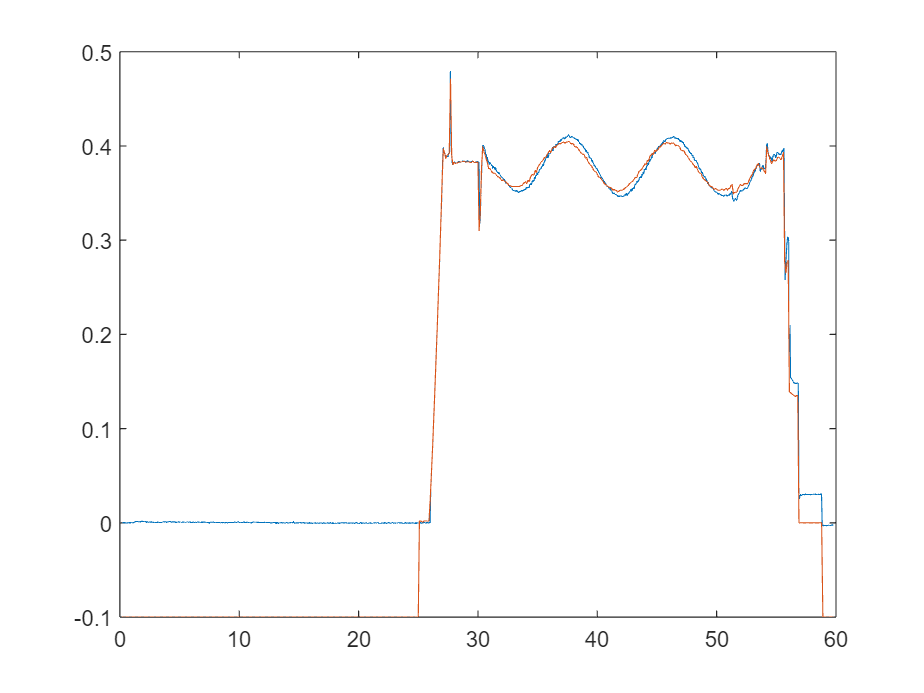


control = [control_data.control_0_,control_data.control_1_,control_data.control_2_,control_data.control_3_];
tc = control_data.timestamp/1000000;
output = [outputs_data.output_0_,outputs_data.output_1_,outputs_data.output_2_,outputs_data.output_3_]/1000-1;
to = outputs_data.timestamp/1000000;

B=[-0.707 0.707 1 1;
    0.707 -0.707 1 1; 
    0.707 0.707 -1 1;
    -0.707 -0.707 -1 1;];
tmp=(B * control')';
plot(tc,tmp(:,1),to,output(:,1))

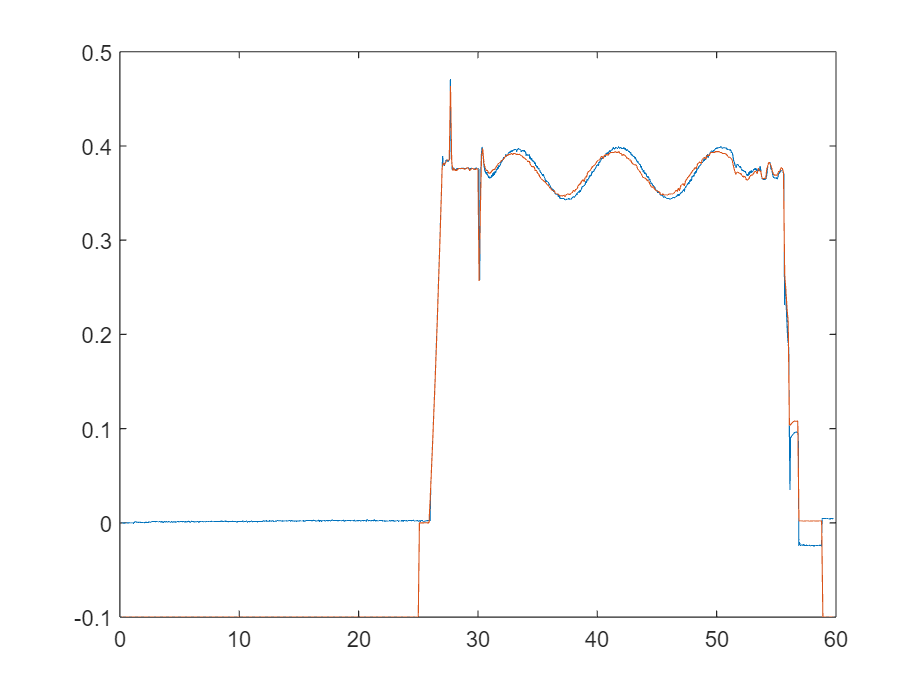

plot(tc,tmp(:,2),to,output(:,2))

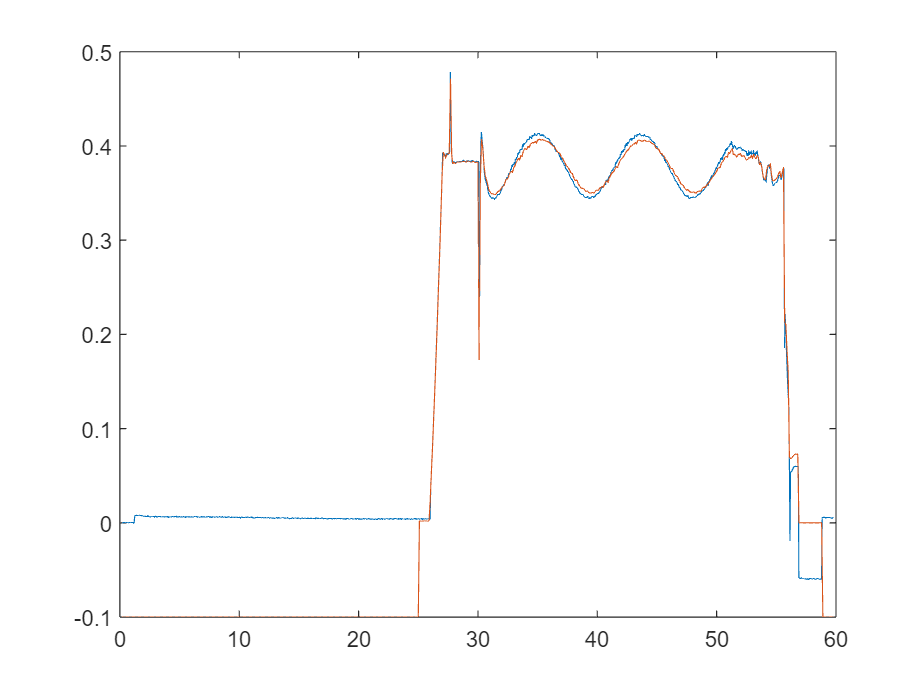

plot(tc,tmp(:,3),to,output(:,3))

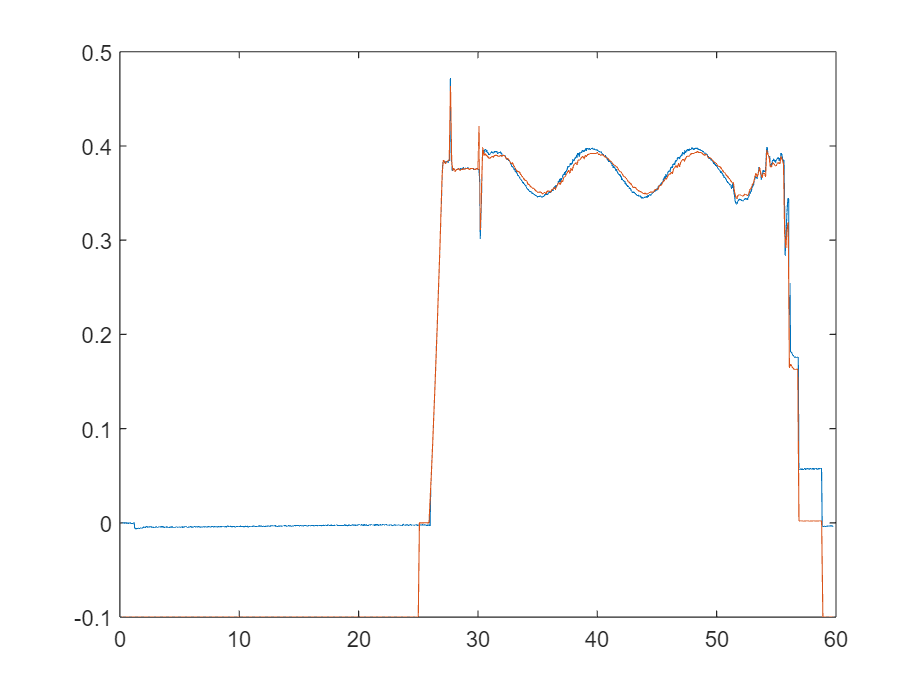

plot(tc,tmp(:,4),to,output(:,4))